# Generation and manipulation of reconstructions with rBioNet

**Author(s): Ines Thiele, Ronan M. T. Fleming, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): **

rBioNet is a reconstruction tool that lets you assemble reconstruction in a user friendly environment. In this tutorial you shall learn how you can use this tool to either start a new reconstruction or load in an existing one, followed by, its analysis. The tool consists of 3 main parts, i.e., metabolite creator, reaction creator and reconstruction creator. The metabolite creator is used to add in metabolites and its associated information, i.e., its elemental formula, charge, identifiers (for e.g., KEGG ID, PubChem ID etc.) and other associated attributes. Alternatively, a text file containing all the necessary information in the same order as in the metabolite database can be loaded directly. The reaction creator is used to formulate reactions and as stated before a text file containing all the necessary information about the reaction abbreviation, description, formula, reversibility, confidence score, notes, references. Alternatively, a text file containing all the necessary information in the same order as in the reaction database can be loaded on to the reaction creator directly. The reconstruction creator is used to load in reactions from the reactions database and then assign GPRs (gene-protein-reaction association), subsystem, add in more information in the notes and reference section. Once you have completed your reconstruction you can look at the S-matrix, identify dead ends, look for neighboring reaction to a particular reaction and plot metabolite connectivity in the reconstruction creator with its statistics function. Below we give you step by step approach on how to do this.

 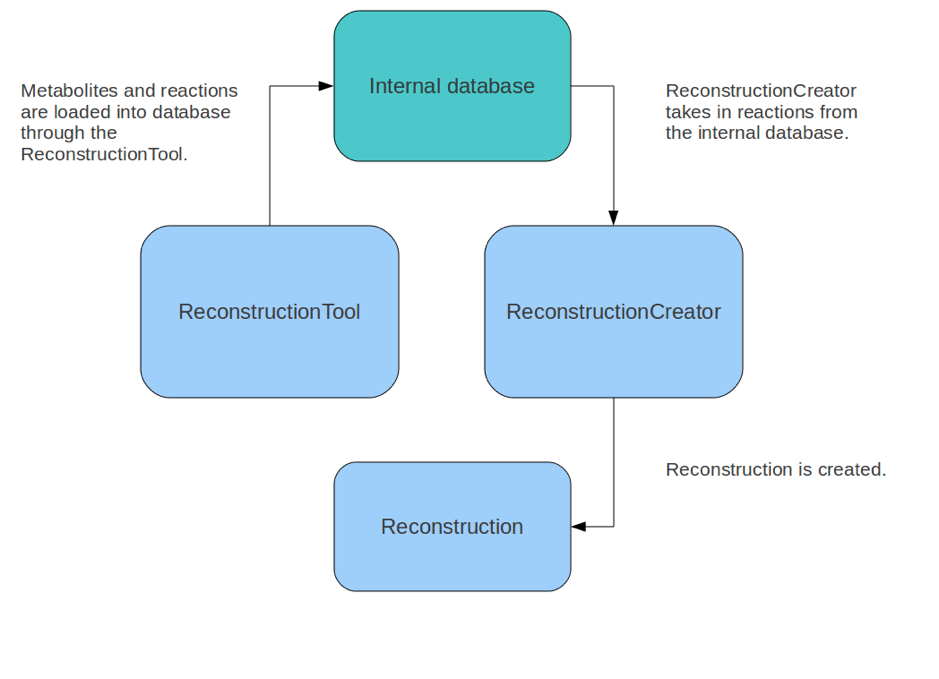

## Features of rBioNet:

***Environment to assemble reconstruction that consists of 3 parts***

- Metabolite creator

- Reaction creator

- Reconstruction creator

***Metabolite creator***

- Associated with metabolite database.

- Used to create new metabolite by :

- Uploading from a text file that contains all the information in the same order as in the database

- Manually filling in all the information

- Loading from other COBRA reconstructions

- Checks for potential duplicate entries.

- Checks done on metabolite abbreviation and charged formula.

- Metabolites are organism and compartment independent.

***Reaction creator ***

-  Methods for addition is same.

- Reactions contain metabolites pre-existing in the metabolite database.

- Checks for duplicate entries, mass and charge balance.

- Reactions are organism independent but compartment specific. Same reaction can occur in different compartment.

- Either start from scratch or load pre-existing reconstruction.

- Can contain only reactions that are present in the reaction database.

- Primarily used to assign GPRs.

- Also to add notes, subsystem etc.

***Add-ons ***

- Reconstruction analyzer

- Checks for dead-end metabolites.

- Gives in suggestion for exchange reactions.

- S-matrix visualization. 

- Neighbor Reactions & Metabolite connectivity.

## EQUIPMENT SETUP

If necessary, initialize the cobra toolbox:

initCobraToolbox

For solving linear programming problems in FBA analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);

This tutorial can be run with `'glpk``'` package as linear programming solver, which does not require additional instalation and configuration. However, for the analysis of large models, such as Recon 3, it is not recommended to use `'glpk``'` but rather industrial strenght solvers, such as the `'gurobi'` package. For detail information, refer to the solver instalation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md)

warning off MATLAB:subscripting:noSubscriptsSpecified

## Steps to load and initiate the Reconstruction Tool

Start up: rBioNet needs a pre-existing database to start up. We provided the database to you that consists of the ten reactions of the glycolysis pathway. Hence, you will see the glycolysis reactions in the reaction creator panel, the metabolites participating in these reactions in the metabolite creator panel.

0. Open MATLAB

1. Add the CobraToolbox provided to you in your path:

In MATLAB window go to *file-> setpath-> add with subfolders-> cobra toolbox folder -> save & close*

 2. Initiate rBioNet by linking the database files. Note that there are three files, corresponding to the reaction database (rxn.mat), metabolite database (metab.mat), and the compartment database (compartments.mat).

rBioNetSettings

 This window below appears

 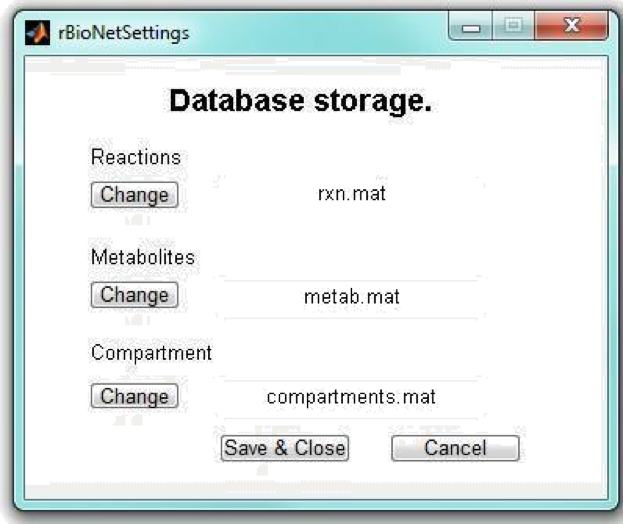

Click on the change tab for reactions and locate to the rxn.mat file, which is provided to you in the folder.

*Reactions-> Change-> rxn.mat->save*

Click on the change tab under metabolites and locate to the metab.mat file, which is provided to you in the Dropbox.

*Metabolites->Change-> metab.mat->save*

Click on the change tab under compartment and locate to the compartments.mat file, which is provided in the Dropbox. 

*Compartment->Change-> compartments.mat -> save*

This is the pre-existing database with glycolysis reactions and you saved it as your current database. You can modify it or remove the reactions as per to your need. 

## Open and nagivating in rBioNet

ReconstructionTool 

 and the rBioNet tool pops up.

Click on the Reaction view table and then show all button which shall let you see all the glycolysis reactions.

Reaction view table: *Reaction creator -> refresh/Show all*

 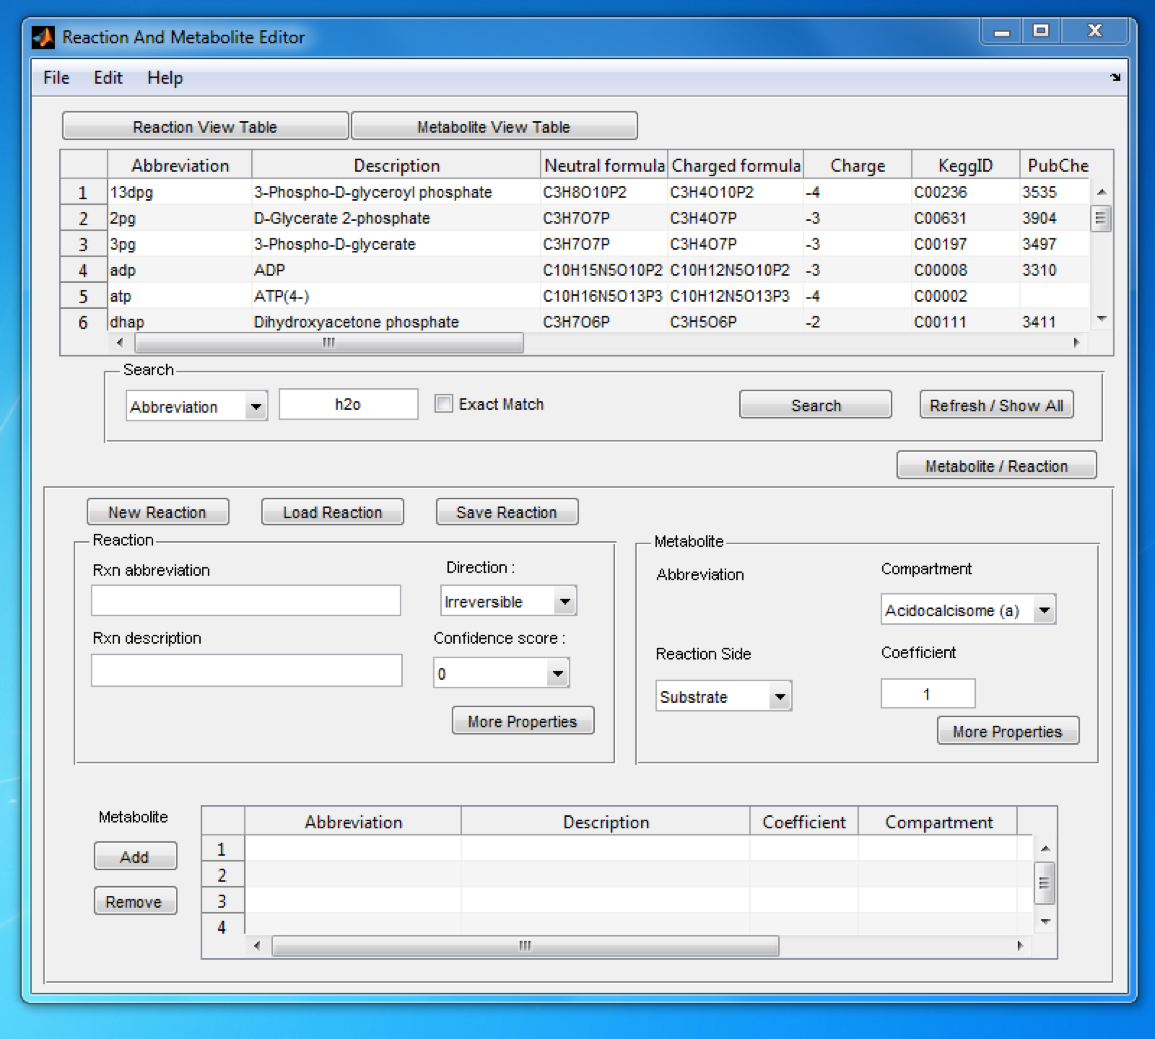

Click on Metabolite view table and then show all button which shall let you see all the glycolysis metabolites

Metabolite view table: *Metabolite creator -> refresh/Show all*

 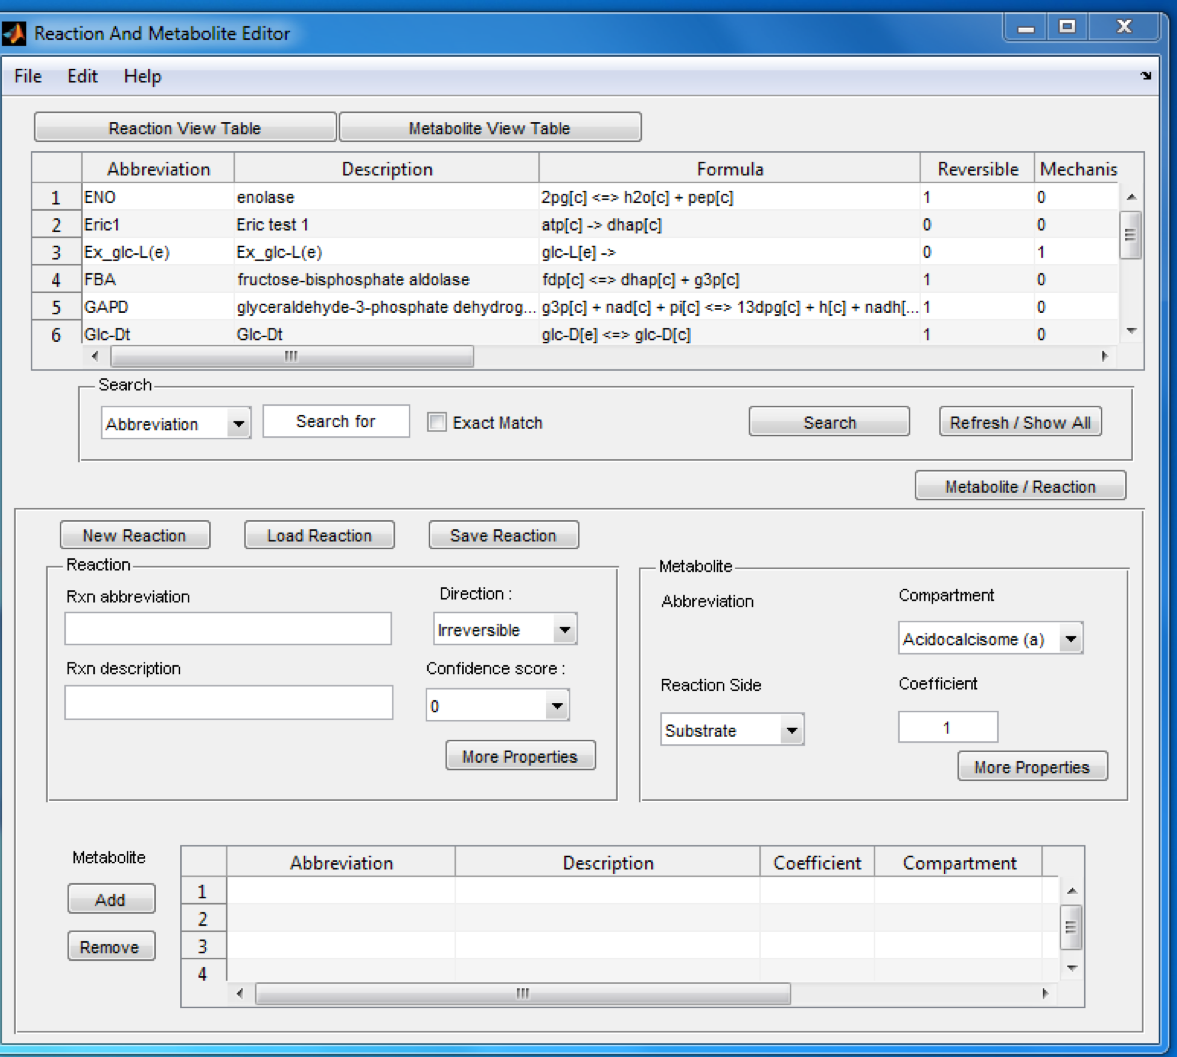

To visualize the reconstruction creator panel go to file and open the model creator 

*File -> Open Model Creator -> Reconstruction Creator*

 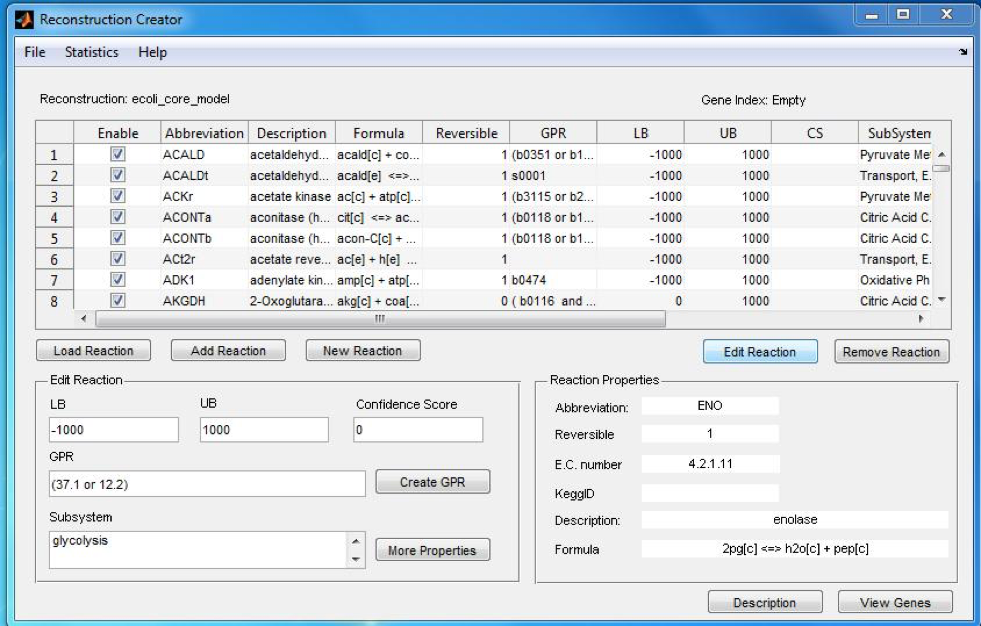

    Figure: Reconstruction Creator with *E. coli*_ core model

**Load in the *****E.coli***** core model in the reconstruction creator panel:**

In the reconstruction creator do as follows

*File->open model -> complete reconstruction-> locate to the E. coli_core_model -> click yes on the reconstruction description bar –> click no on the load gene index bar.*

Now, we see the content of the *E. coli*_core model in the reconstruction creator (see Figure above).

In this page, click on *statistics button -> reconstruction analyzer*

and visualize the S-matrix, dead end metabolites.

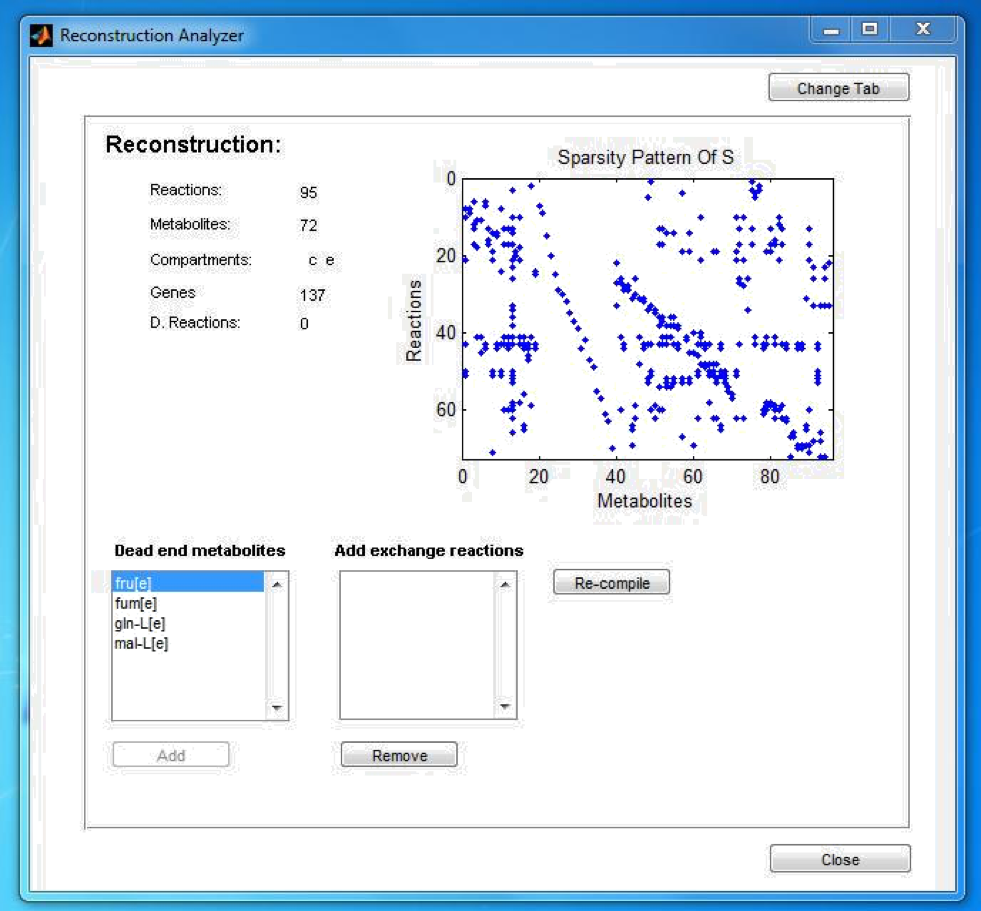

                         Figure: S-matrix and dead end metabolites for the *E. coli* core model

## Adding a new metabolite

Now, let’s learn how to add a new metabolite.

Come back to the reaction and metabolite editor panel 

                                                                                                                    Click on Metabolite/Reaction tab

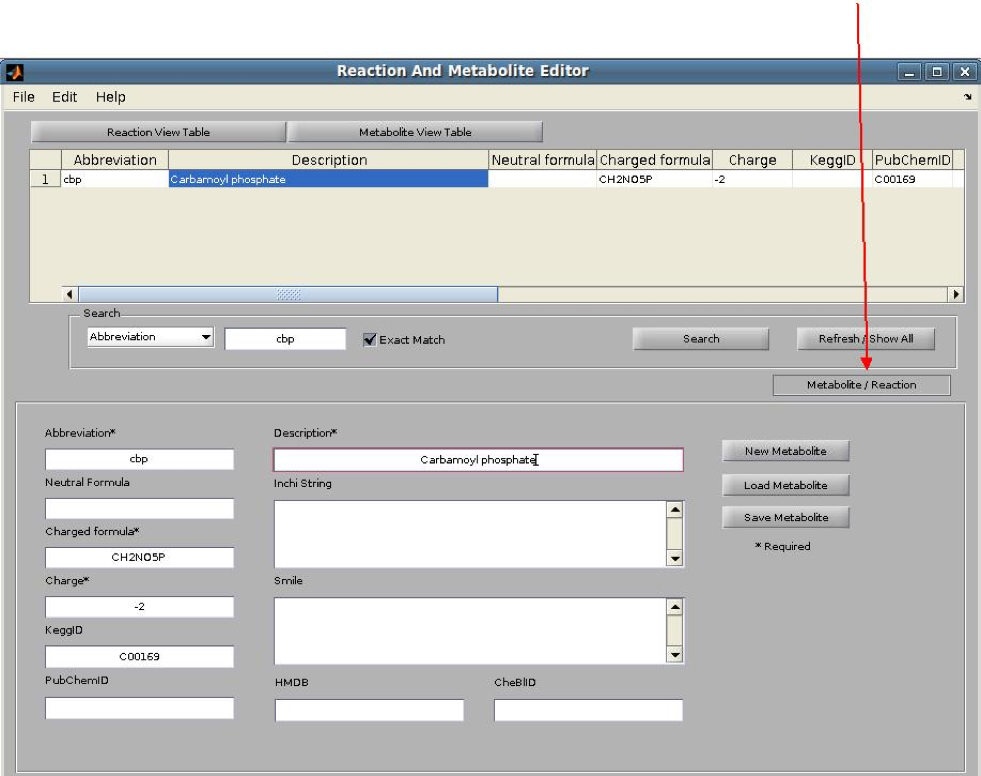

- addition of first metabolite abbreviation along with required information: formula, charge and metabolite id 

- save metabolite

- continue for all the metabolites provided in the 'ureacycle_mets.txt'.

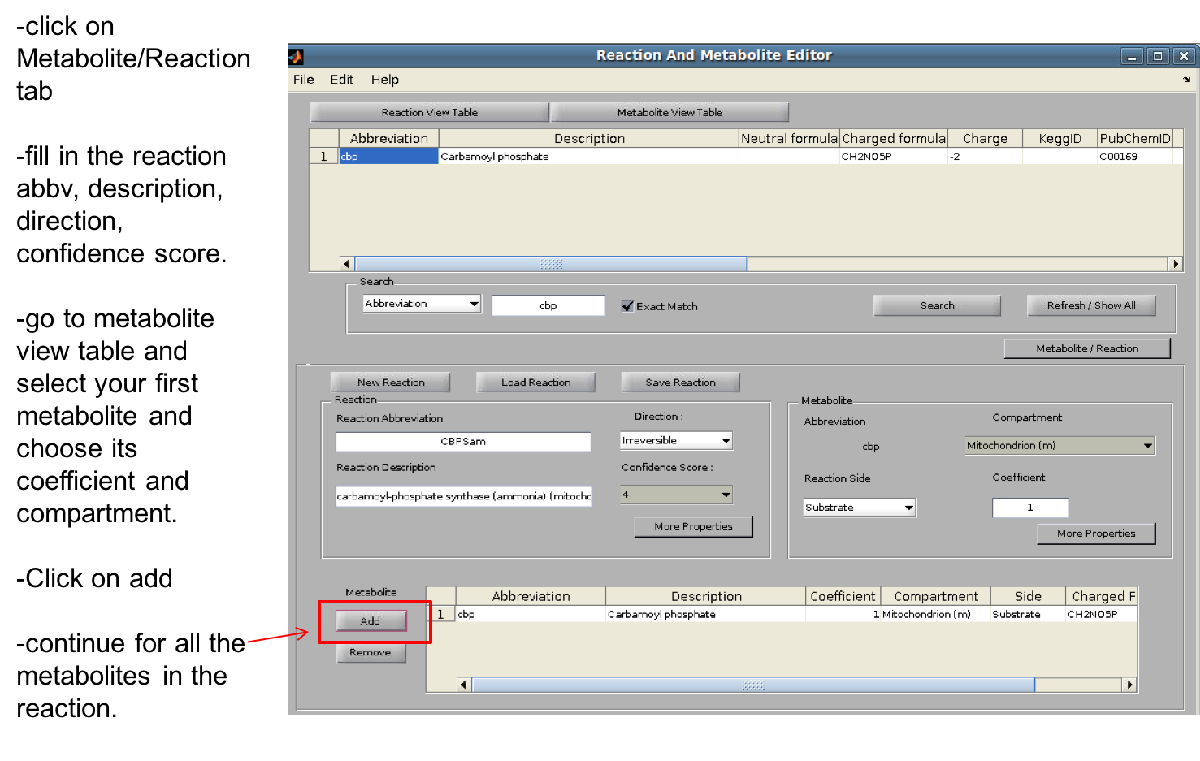

** ALTERNATIVE**

Alternatively load in the ureacycle_mets.txt file provided in the tutorial folder.

*Go to file-> add text file -> with metabolite -> locate* to ureacycle_mets.txt 

Click yes on each bar that appears.

When you are doing this for your reconstruction, make sure that each information is **absolutely correct** and thoroughly checked before you make the addition.

## Adding new reaction

 Again click on Metabolite/Reaction tab shown above. The window below appears.

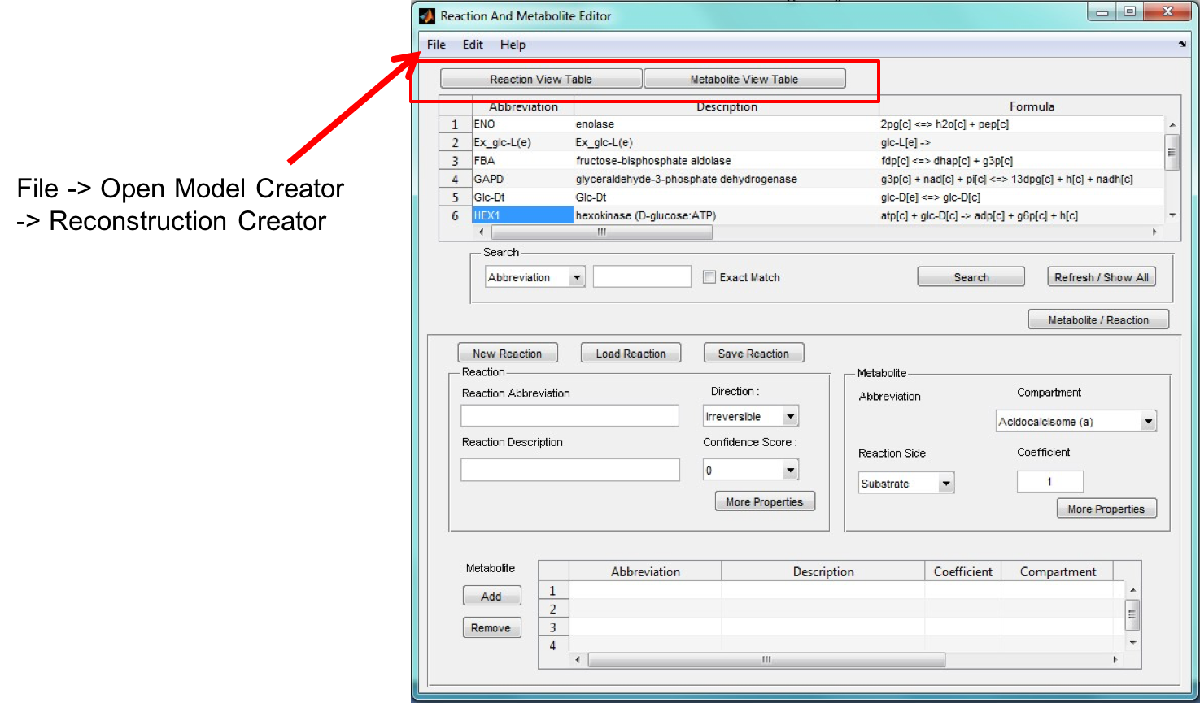

Then, click 'New Reaction' and fill in the reaction abbreviation, description, direction, confidence score.

                                    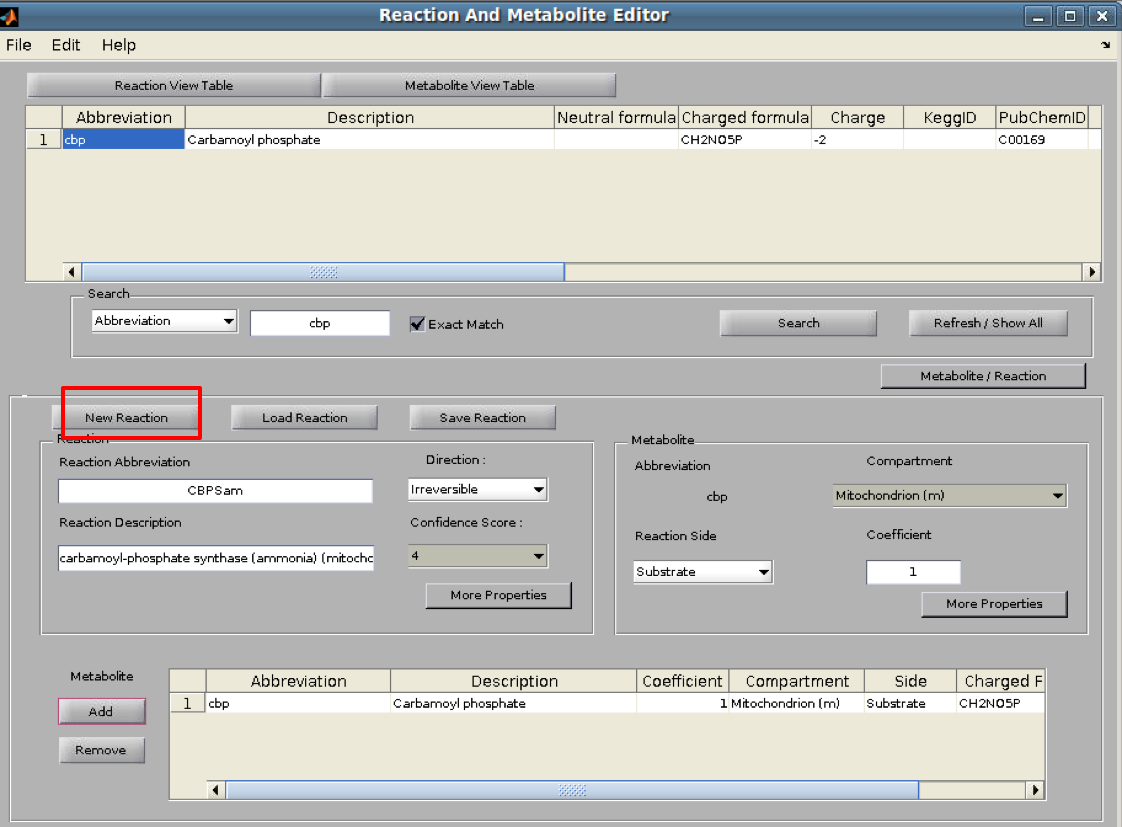

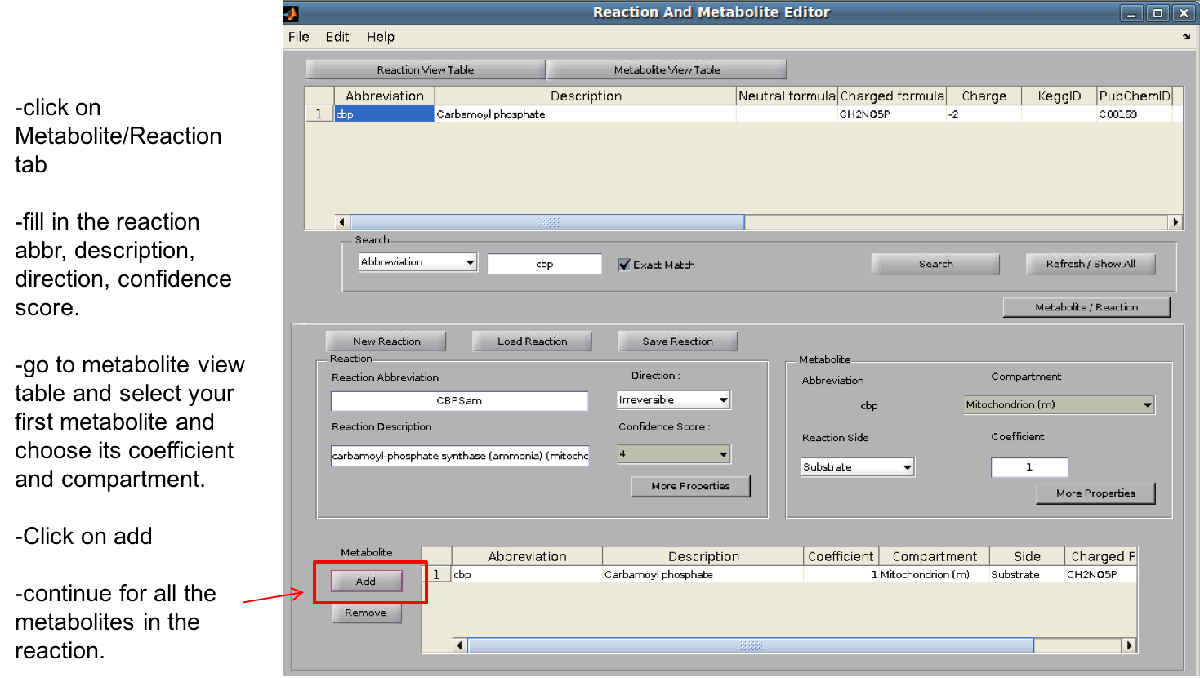

Click save reaction

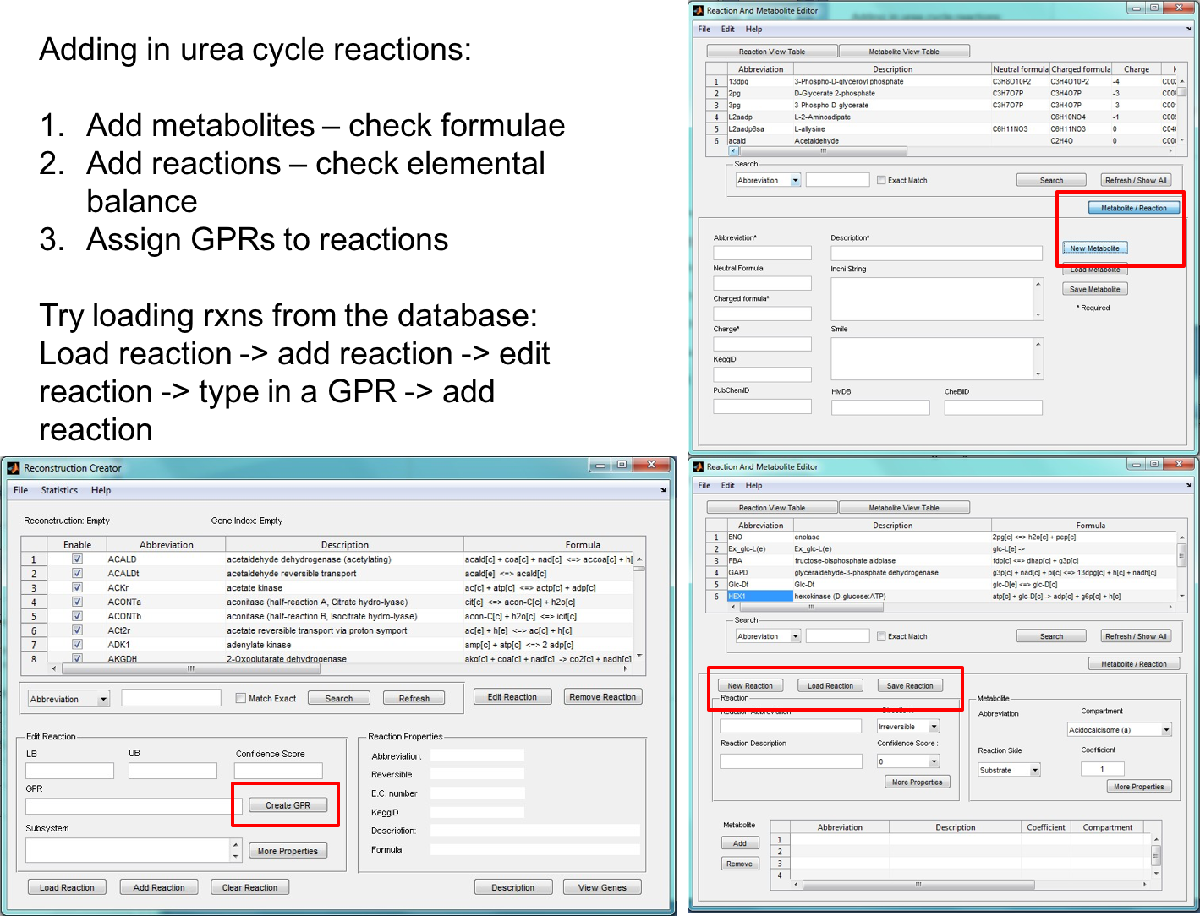

For the assignment of GPRs to reaction ('Create GPR') please also see next section.

Now, the tool checks for elemental and charge balancing and warns you if there is an error.

Click yes if everything is correct in the follow up bar to save your reaction.

Repeat this for the five reactions given in the hand out.

**ALTERNATIVE**

Alternatively, you can load in the text file containing the reactions provided in the tutorial folder (i.e., ureacycle_rxns.txt) and save it.

When you do this for your reconstruction, make sure all the information are absolutely correct.

## Assigning GPRs to the reactions

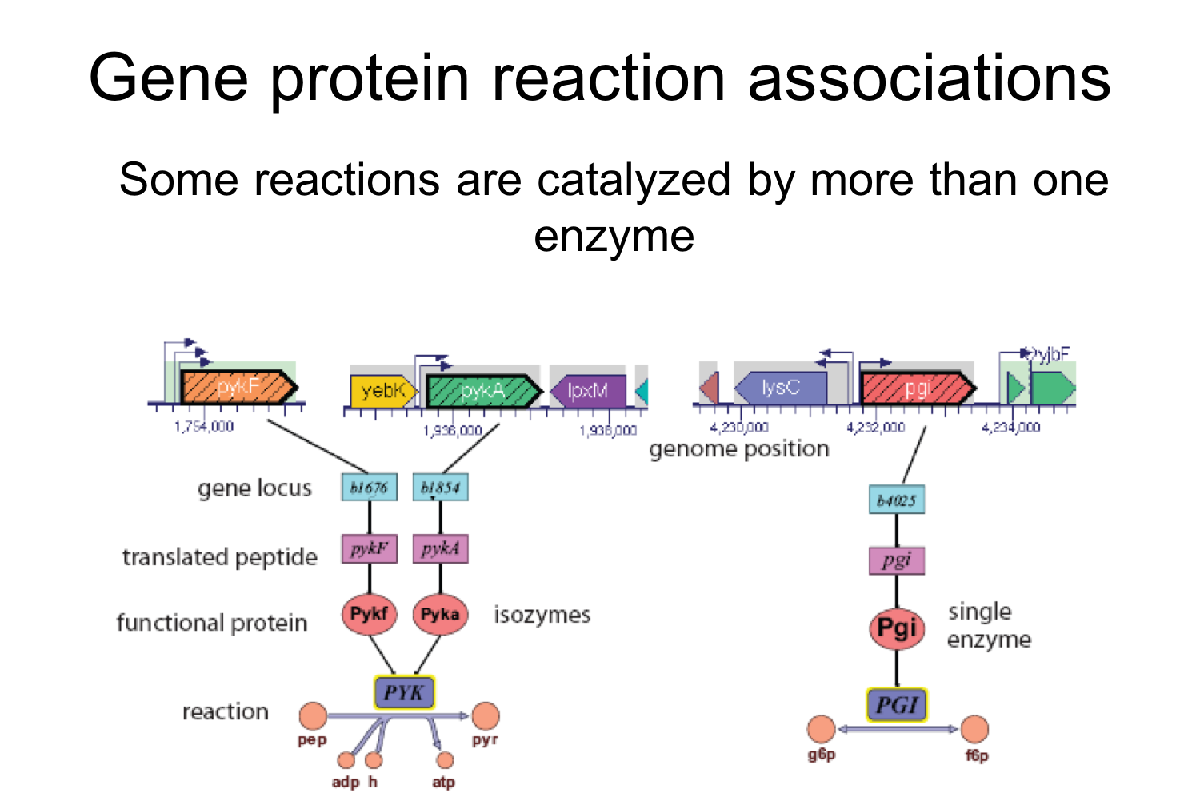

•      Open model creator 

•      Click load reaction 

•      Select the reaction you want to assign GPR and then load in onto the reconstruction creator page 

•      Click add rxn 

•      Click on create GPR 

•      Go to file->load gene index 

•      Click on genes you want to assign

•      Click add genes

•      Click on the genes and specify the and /or rule   

**                                                                                                                                            Add Genes tab**

    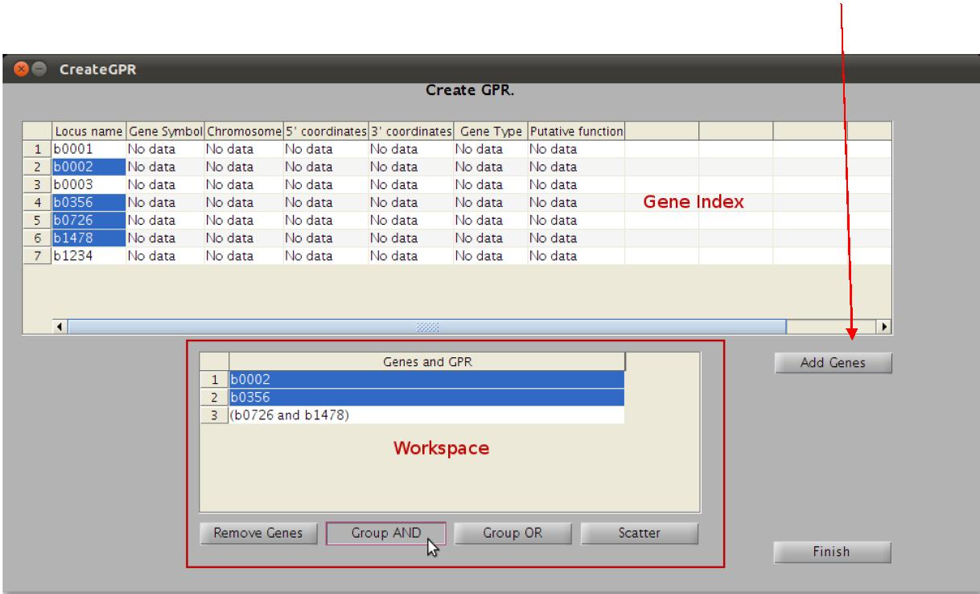

- Once the GPR has been assigned and other edits done (for e.g., addition of subsystem, further notes and references) click the add reaction button in the reconstruction creator. 

- The bar for replacing the current reaction appears and you should click yes in it. 

- Now you should be able to see the new edited (i.e., GPR associated) reaction on the top panel of the reconstruction creator. 

- Once you have finished with all the reactions, go to file and save your reconstruction as a model. 

- In case you made any errors while adding metabolites or reactions manually in the reaction/ metabolite editor, you can load in the reaction/ metabolite database (i.e., rxn.mat/ metab.mat files) into the MATLAB workspace and delete/ edit it in the variable editor in the MATLAB and save it. This shall be your new database from now on. 

- Make sure that you never make errors while filling in the information in the database. 

## Explore reconstruction analyzer

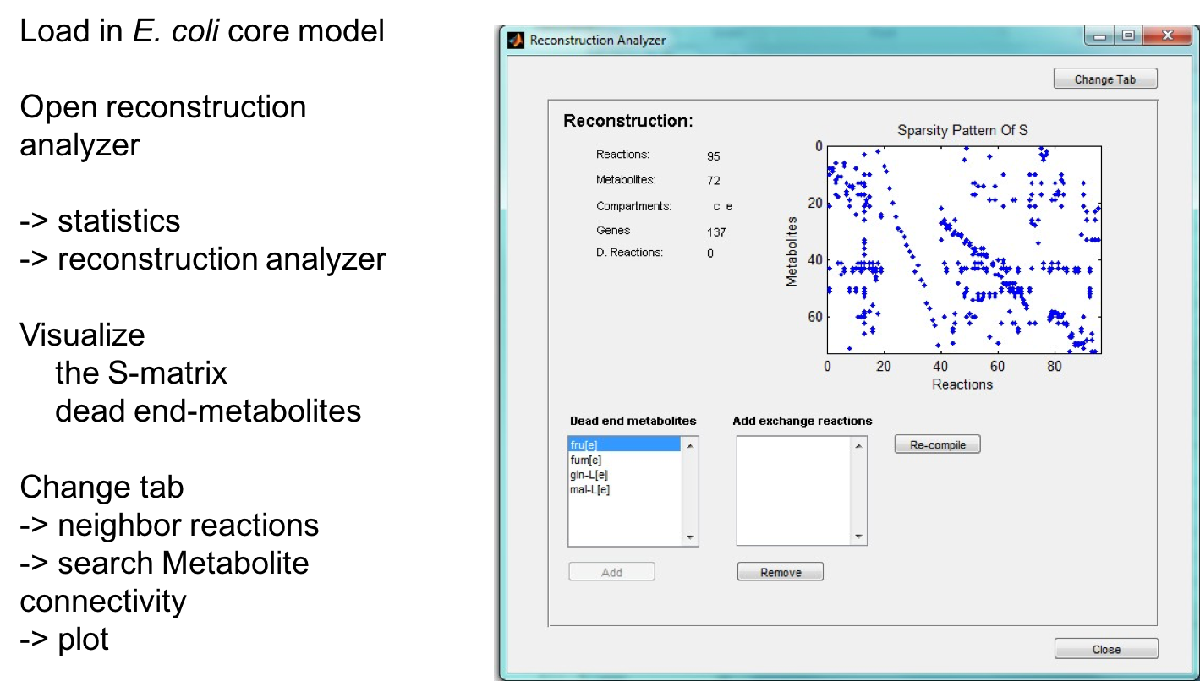

## Reference

[1[ Thorleifsson SG, Thiele I. Bioinformatics. 2011 Jul 15;27(14):2009-10. 